clear variables;
%clear all;
%([xmin ymin width height])
maxBitNumber=65535;

# **Folios en blanco**

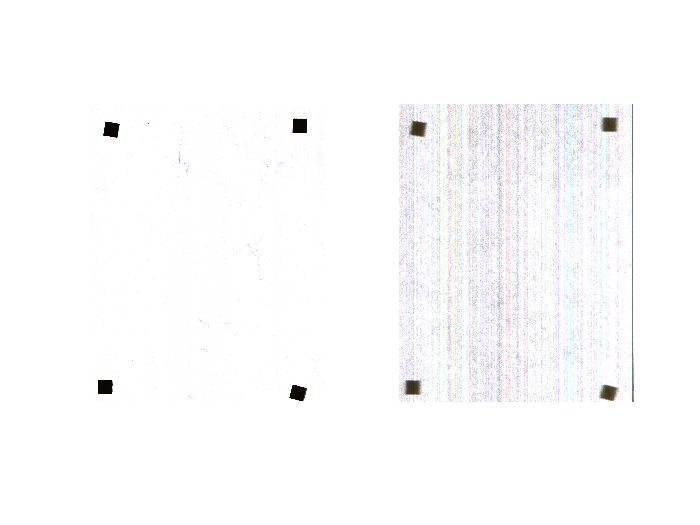

filmPathB1 = 'BLANCO1.tif';
IB1=imread(filmPathB1);
filmPathB2 = 'BLANCO2.tif';
IB2=imread(filmPathB2);
figure
subplot(1,2,1)
imshow(IB1)
subplot(1,2,2)
imshow(IB2)

#### **Análisis folio blanco**

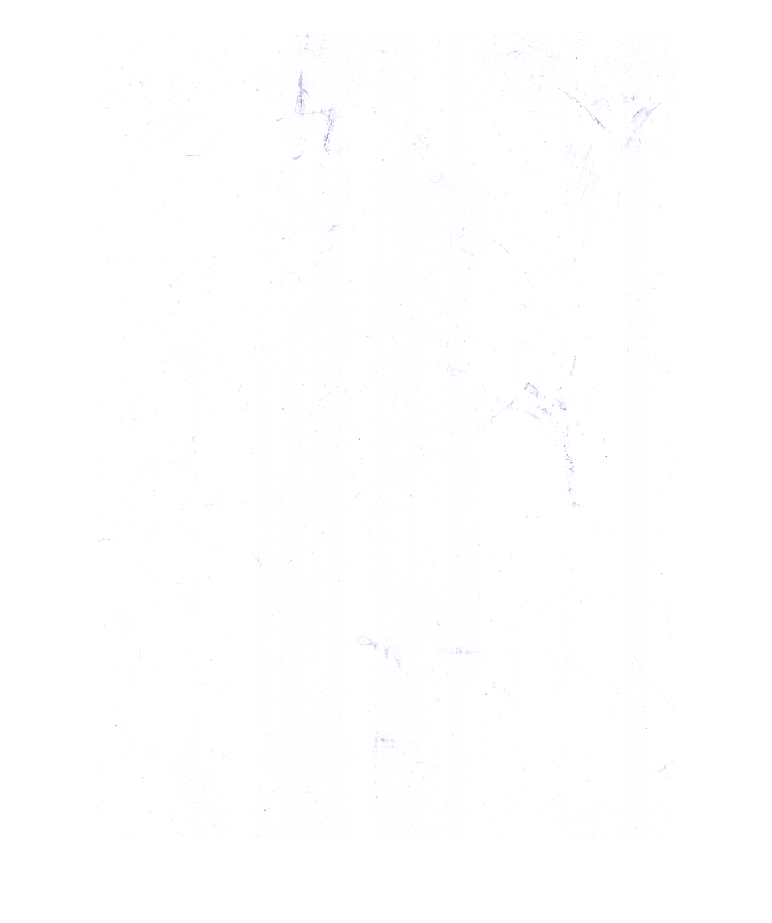

%Recortar la imagen y obtener solo la parte central
Recorte=[137.5 176.5 871 1213];
IB1C=imcrop(IB1,Recorte);
figure
imshow(IB1C)

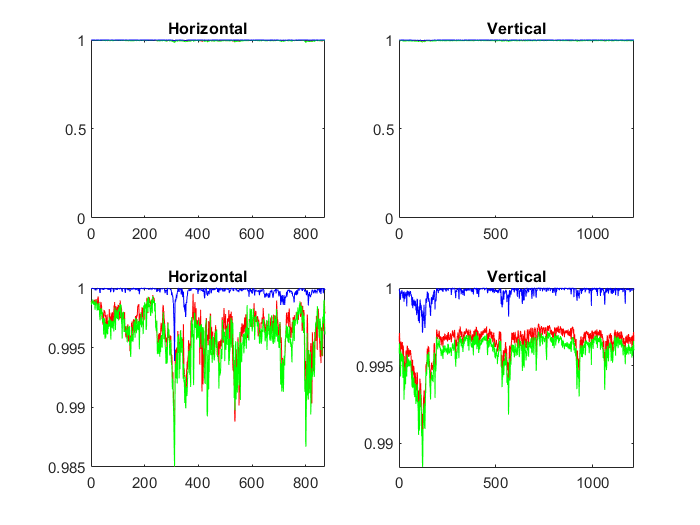

RB1C = double(IB1C(:,:,1)) / maxBitNumber;
GB1C = double(IB1C(:,:,2)) / maxBitNumber;
BB1C = double(IB1C(:,:,3)) / maxBitNumber;
figure
subplot(2,2,1)
hold off
plot(mean(RB1C),'r'); hold on
plot(mean(GB1C),'g');
plot(mean(BB1C),'b')
title('Horizontal')
xlim([0 Recorte(3)])
ylim([0 1])

subplot(2,2,2)
hold off
plot(mean(RB1C,2),'r'); hold on
plot(mean(GB1C,2),'g');
plot(mean(BB1C,2),'b')
title('Vertical')
xlim([0 Recorte(4)])
ylim([0 1])

subplot(2,2,3)
hold off
plot(mean(RB1C),'r'); hold on
plot(mean(GB1C),'g');
plot(mean(BB1C),'b')
title('Horizontal')
xlim([0 Recorte(3)])


subplot(2,2,4)
hold off
plot(mean(RB1C,2),'r'); hold on
plot(mean(GB1C,2),'g');
plot(mean(BB1C,2),'b')
title('Vertical')
xlim([0 Recorte(4)])

# **Radiocrómicas**

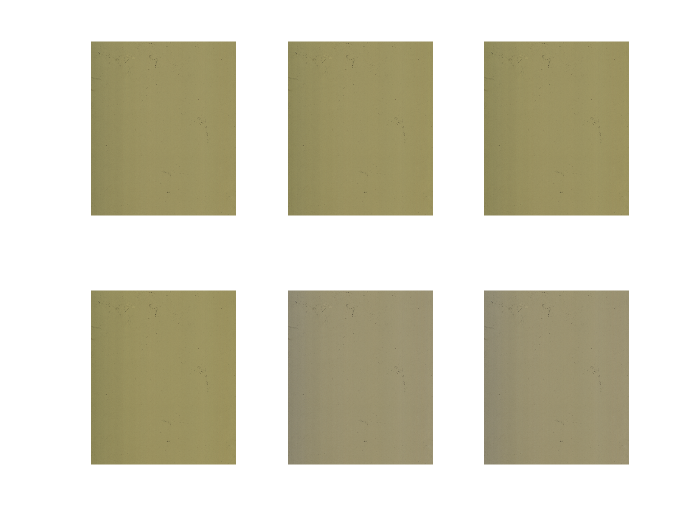

filmPath = 'RC1(sin)-buena.tif';
recorte=[29.5 169.5 1025 1230];
I1 = imread(filmPath);
I1R = imcrop(I1,recorte);
R1R = double(I1R(:,:,1)) / maxBitNumber;
G1R = double(I1R(:,:,2)) / maxBitNumber;
B1R = double(I1R(:,:,3)) / maxBitNumber;

filmPath2 = 'RC1(sin)-buena (2).tif';
I2 = imread(filmPath2);
I2R = imcrop(I2,recorte);
R2R = double(I2R(:,:,1)) / maxBitNumber;
G2R = double(I2R(:,:,2)) / maxBitNumber;
B2R = double(I2R(:,:,3)) / maxBitNumber;

filmPath3 = 'RC1(sin)-buena (3).tif';
I3 = imread(filmPath3);
I3R = imcrop(I3,recorte);
R3R = double(I3R(:,:,1)) / maxBitNumber;
G3R = double(I3R(:,:,2)) / maxBitNumber;
B3R = double(I3R(:,:,3)) / maxBitNumber;

filmPath4 = 'RC1(sin)-buena (4).tif';
I4 = imread(filmPath4);
I4R = imcrop(I4,recorte);
R4R = double(I4R(:,:,1)) / maxBitNumber;
G4R = double(I4R(:,:,2)) / maxBitNumber;
B4R = double(I4R(:,:,3)) / maxBitNumber;

filmPath5 = 'RC1(sin)-buena (5).tif';
I5 = imread(filmPath5);
I5R = imcrop(I5,recorte);
R5R = double(I5R(:,:,1)) / maxBitNumber;
G5R = double(I5R(:,:,2)) / maxBitNumber;
B5R = double(I5R(:,:,3)) / maxBitNumber;

filmPath6 = 'RC1(sin)-buena (6).tif';
I6 = imread(filmPath6);
I6R = imcrop(I6,recorte);
R6R = double(I6R(:,:,1)) / maxBitNumber;
G6R = double(I6R(:,:,2)) / maxBitNumber;
B6R = double(I6R(:,:,3)) / maxBitNumber;

figure
subplot(2,3,1)
imshow(I1R);
subplot(2,3,2)
imshow(I2R);
subplot(2,3,3)
imshow(I3R);
subplot(2,3,4)
imshow(I4R);
subplot(2,3,5)
imshow(I5R);
subplot(2,3,6)
imshow(I6R);

## Análisis 4 Primeras

#### Pixel a pixel 

juntasR = zeros(recorte(4)+1,recorte(3)+1,3,4);

% Rojo
juntasR(:,:,1,1) = R1R;
juntasR(:,:,1,2) = R2R;
juntasR(:,:,1,3) = R3R;
juntasR(:,:,1,4) = R4R;

% Verde
juntasR(:,:,2,1) = G1R;
juntasR(:,:,2,2) = G2R;
juntasR(:,:,2,3) = G3R;
juntasR(:,:,2,4) = G4R;

% Azul 
juntasR(:,:,3,1) = B1R;
juntasR(:,:,3,2) = B2R;
juntasR(:,:,3,3) = B3R;
juntasR(:,:,3,4) = B4R;


%Desviación estándar de las matrices pixel a pixel de la 4 dimensión
desvRR = std(juntasR(:,:,1,:),0,4)

desvRR =     0.0007    0.0010    0.0017    0.0015    0.0010    0.0014    0.0008    0.0038    0.0010    0.0011    0.0010    0.0013    0.0017    0.0007    0.0007    0.0011    0.0023    0.0014    0.0012    0.0022    0.0026    0.0008    0.0020    0.0010    0.0014    0.0019    0.0018    0.0017    0.0028    0.0016    0.0014    0.0024    0.0013    0.0015    0.0007    0.0008    0.0004    0.0010    0.0017    0.0028    0.0018    0.0015    0.0013    0.0013    0.0010    0.0022    0.0009    0.0018    0.0019    0.0002
    0.0012    0.0017    0.0015    0.0010    0.0010    0.0006    0.0020    0.0017    0.0015    0.0013    0.0014    0.0007    0.0014    0.0005    0.0013    0.0012    0.0012    0.0008    0.0014    0.0012    0.0007    0.0016    0.0022    0.0009    0.0002    0.0007    0.0012    0.0010    0.0010    0.0015    0.0005    0.0013    0.0013    0.0013    0.0009    0.0009    0.0015    0.0010    0.0023    0.0026    0.0018    0.0013    0.0013    0.0025    0.0007    0.0012    0.0002    0.0013    0.0009

desvGR = std(juntasR(:,:,2,:),0,4)

desvGR =     0.0012    0.0014    0.0003    0.0004    0.0020    0.0006    0.0013    0.0036    0.0010    0.0013    0.0013    0.0011    0.0004    0.0010    0.0006    0.0005    0.0016    0.0007    0.0009    0.0014    0.0012    0.0005    0.0014    0.0013    0.0004    0.0015    0.0013    0.0018    0.0021    0.0015    0.0020    0.0012    0.0011    0.0016    0.0021    0.0014    0.0006    0.0011    0.0013    0.0013    0.0019    0.0010    0.0002    0.0005    0.0010    0.0011    0.0006    0.0011    0.0010    0.0008
    0.0018    0.0023    0.0015    0.0006    0.0007    0.0003    0.0027    0.0017    0.0015    0.0011    0.0010    0.0008    0.0014    0.0012    0.0011    0.0020    0.0022    0.0009    0.0010    0.0018    0.0004    0.0010    0.0014    0.0011    0.0008    0.0018    0.0007    0.0007    0.0008    0.0018    0.0011    0.0015    0.0014    0.0011    0.0011    0.0014    0.0011    0.0008    0.0018    0.0018    0.0021    0.0016    0.0019    0.0033    0.0016    0.0011    0.0014    0.0016    0.0007

desvBR = std(juntasR(:,:,3,:),0,4)

desvBR =     0.0027    0.0028    0.0039    0.0026    0.0026    0.0039    0.0031    0.0038    0.0030    0.0036    0.0036    0.0030    0.0029    0.0030    0.0029    0.0031    0.0037    0.0037    0.0036    0.0042    0.0028    0.0032    0.0026    0.0027    0.0030    0.0036    0.0030    0.0028    0.0028    0.0027    0.0031    0.0029    0.0030    0.0030    0.0036    0.0027    0.0029    0.0031    0.0024    0.0035    0.0036    0.0028    0.0028    0.0035    0.0032    0.0029    0.0034    0.0032    0.0024    0.0028
    0.0027    0.0030    0.0032    0.0026    0.0021    0.0032    0.0035    0.0027    0.0027    0.0031    0.0029    0.0032    0.0030    0.0037    0.0035    0.0029    0.0038    0.0032    0.0031    0.0039    0.0029    0.0033    0.0029    0.0026    0.0025    0.0034    0.0033    0.0024    0.0028    0.0029    0.0023    0.0025    0.0028    0.0027    0.0036    0.0025    0.0028    0.0024    0.0037    0.0036    0.0031    0.0026    0.0033    0.0029    0.0030    0.0031    0.0034    0.0029    0.0026

#### **Media**

%Matriz promedio
mediaRR = mean(juntasR(:,:,1,:),4);
mediaGR = mean(juntasR(:,:,2,:),4);
mediaBR = mean(juntasR(:,:,3,:),4);

RRfinal = round(maxBitNumber*mediaRR,0);
GRfinal = round(maxBitNumber*mediaGR,0);
BRfinal = round(maxBitNumber*mediaBR,0);


%desviación estándar de los elementos de cada columna 1x1183
dsv_MediaRRc=std(mediaRR,0,1)

dsv_MediaRRc =     0.0110    0.0106    0.0095    0.0094    0.0092    0.0085    0.0082    0.0081    0.0080    0.0079    0.0082    0.0077    0.0075    0.0073    0.0071    0.0071    0.0075    0.0074    0.0073    0.0088    0.0076    0.0068    0.0076    0.0072    0.0071    0.0068    0.0067    0.0060    0.0065    0.0073    0.0072    0.0071    0.0068    0.0065    0.0069    0.0063    0.0069    0.0063    0.0060    0.0068    0.0075    0.0068    0.0065    0.0077    0.0068    0.0074    0.0090    0.0077    0.0092    0.0094


dsv_MediaGRc=std(mediaGR,0,1)

dsv_MediaGRc =     0.0116    0.0113    0.0101    0.0099    0.0097    0.0090    0.0087    0.0086    0.0085    0.0083    0.0086    0.0080    0.0077    0.0076    0.0074    0.0073    0.0079    0.0076    0.0076    0.0089    0.0078    0.0071    0.0078    0.0073    0.0073    0.0071    0.0071    0.0062    0.0068    0.0076    0.0075    0.0075    0.0071    0.0068    0.0073    0.0066    0.0072    0.0066    0.0064    0.0071    0.0077    0.0070    0.0067    0.0080    0.0070    0.0074    0.0091    0.0077    0.0091    0.0095


dsv_MediaBRc=std(mediaBR,0,1)

dsv_MediaBRc =     0.0090    0.0089    0.0082    0.0080    0.0078    0.0073    0.0072    0.0070    0.0069    0.0068    0.0068    0.0065    0.0063    0.0061    0.0059    0.0059    0.0061    0.0060    0.0061    0.0070    0.0063    0.0058    0.0061    0.0060    0.0060    0.0059    0.0058    0.0053    0.0055    0.0060    0.0060    0.0060    0.0058    0.0057    0.0059    0.0057    0.0060    0.0056    0.0054    0.0059    0.0062    0.0057    0.0055    0.0062    0.0057    0.0060    0.0069    0.0062    0.0076    0.0078


%desviación estándar de los elementos de cada fila 1500x1
dsv_MediaRRf=std(mediaRR,0,2)

dsv_MediaRRf =     0.0155
    0.0148
    0.0153
    0.0152
    0.0156
    0.0152
    0.0145
    0.0147
    0.0151
    0.0143


dsv_MediaGRf=std(mediaGR,0,2)

dsv_MediaGRf =     0.0127
    0.0119
    0.0124
    0.0123
    0.0127
    0.0123
    0.0116
    0.0117
    0.0121
    0.0113


dsv_MediaBRf=std(mediaBR,0,2)

dsv_MediaBRf =     0.0099
    0.0094
    0.0096
    0.0095
    0.0098
    0.0095
    0.0090
    0.0092
    0.0093
    0.0088


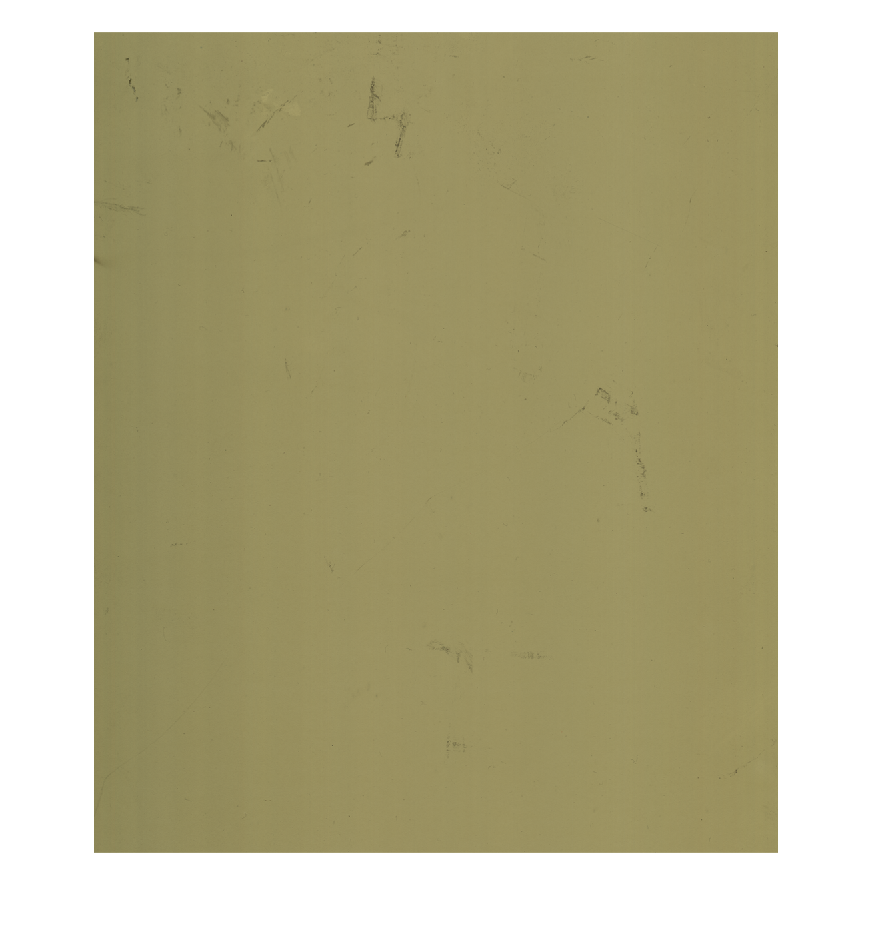



% Dibujar 
imFinalR = uint16(zeros(recorte(4)+1,recorte(3)+1,3));
imFinalR(:,:,1) = uint16(RRfinal);
imFinalR(:,:,2) = uint16(GRfinal);
imFinalR(:,:,3) = uint16(BRfinal);
figure
imshow(imFinalR)

#### Variación horizontal

juntasmeanHR = zeros(size(mean(double(I1R(:,:,1)) / maxBitNumber),1),size(mean(double(I1R(:,:,1)) / maxBitNumber),2),3,4);
%Promedio: 1x1183

%Rojo
juntasmeanHR(:,:,1,1) = mean(double(I1R(:,:,1)) / maxBitNumber);
juntasmeanHR(:,:,1,2) = mean(double(I2R(:,:,1)) / maxBitNumber);
juntasmeanHR(:,:,1,3) = mean(double(I3R(:,:,1)) / maxBitNumber);
juntasmeanHR(:,:,1,4) = mean(double(I4R(:,:,1)) / maxBitNumber);

%Verde
juntasmeanHR(:,:,2,1) = mean(double(I1R(:,:,2)) / maxBitNumber);
juntasmeanHR(:,:,2,2) = mean(double(I2R(:,:,2)) / maxBitNumber);
juntasmeanHR(:,:,2,3) = mean(double(I3R(:,:,2)) / maxBitNumber);
juntasmeanHR(:,:,2,4) = mean(double(I4R(:,:,2)) / maxBitNumber);


%Azul
juntasmeanHR(:,:,3,1) = mean(double(I1R(:,:,3)) / maxBitNumber);
juntasmeanHR(:,:,3,2) = mean(double(I2R(:,:,3)) / maxBitNumber);
juntasmeanHR(:,:,3,3) = mean(double(I3R(:,:,3)) / maxBitNumber);
juntasmeanHR(:,:,3,4) = mean(double(I4R(:,:,3)) / maxBitNumber);

desvRmeanHR = std(juntasmeanHR(:,:,1,:),0,4)

desvRmeanHR =     0.0006    0.0005    0.0005    0.0005    0.0007    0.0006    0.0005    0.0008    0.0003    0.0003    0.0003    0.0006    0.0005    0.0004    0.0005    0.0005    0.0007    0.0006    0.0005    0.0005    0.0009    0.0007    0.0006    0.0006    0.0006    0.0006    0.0009    0.0007    0.0003    0.0004    0.0006    0.0009    0.0005    0.0004    0.0006    0.0007    0.0004    0.0004    0.0006    0.0007    0.0006    0.0006    0.0006    0.0003    0.0004    0.0006    0.0004    0.0005    0.0009    0.0006


desvGmeanHR = std(juntasmeanHR(:,:,2,:),0,4)

desvGmeanHR = 	1.0e+-3 *

    0.4404    0.3433    0.1331    0.2630    0.2601    0.4043    0.4389    0.4242    0.2912    0.2696    0.1728    0.4679    0.3144    0.1881    0.2934    0.2986    0.3931    0.3572    0.2706    0.3930    0.2578    0.4191    0.5311    0.4766    0.2742    0.2575    0.4668    0.7418    0.3911    0.4270    0.3546    0.3723    0.3484    0.3236    0.4481    0.3424    0.5565    0.2571    0.2875    0.4411    0.3811    0.2005    0.4263    0.0604    0.4332    0.5517    0.6307    0.5255    0.4669    0.3164


desvBmeanHR = std(juntasmeanHR(:,:,3,:),0,4)

desvBmeanHR =     0.0030    0.0031    0.0032    0.0030    0.0028    0.0030    0.0030    0.0030    0.0030    0.0030    0.0032    0.0030    0.0030    0.0030    0.0030    0.0030    0.0028    0.0028    0.0029    0.0030    0.0029    0.0029    0.0029    0.0027    0.0029    0.0029    0.0030    0.0029    0.0028    0.0026    0.0027    0.0028    0.0028    0.0029    0.0029    0.0029    0.0029    0.0028    0.0029    0.0029    0.0027    0.0028    0.0029    0.0029    0.0028    0.0028    0.0026    0.0028    0.0028    0.0029



%Variación horizontal de la media

%desviación estándar de los elementos de cada fila 1500x1
%Rojo
dsv_MediaRmeanHfR=std(mean(juntasmeanHR(:,:,1,:),4),0,2)

dsv_MediaRmeanHfR = 0.0166

%Verde
dsv_MediaGmeanHfR=std(mean(juntasmeanHR(:,:,2,:),4),0,2)

dsv_MediaGmeanHfR = 0.0133

%Azul
dsv_MediaBmeanHfR=std(mean(juntasmeanHR(:,:,3,:),4),0,2)

dsv_MediaBmeanHfR = 0.0100

#### Variación vertical

juntasmeanVR = zeros(size(mean(double(I1R(:,:,1)) / maxBitNumber,2),1),size(mean(double(I1R(:,:,1)) / maxBitNumber,2),2),3,4);

%Promedio: 1500x1
%Rojo
juntasmeanVR(:,:,1,1) = mean(double(I1R(:,:,1)) / maxBitNumber,2);
juntasmeanVR(:,:,1,2) = mean(double(I2R(:,:,1)) / maxBitNumber,2);
juntasmeanVR(:,:,1,3) = mean(double(I3R(:,:,1)) / maxBitNumber,2);
juntasmeanVR(:,:,1,4) = mean(double(I4R(:,:,1)) / maxBitNumber,2);

%Verde
juntasmeanVR(:,:,2,1) = mean(double(I1R(:,:,2)) / maxBitNumber,2);
juntasmeanVR(:,:,2,2) = mean(double(I2R(:,:,2)) / maxBitNumber,2);
juntasmeanVR(:,:,2,3) = mean(double(I3R(:,:,2)) / maxBitNumber,2);
juntasmeanVR(:,:,2,4) = mean(double(I4R(:,:,2)) / maxBitNumber,2);

%Azul
juntasmeanVR(:,:,3,1) = mean(double(I1R(:,:,3)) / maxBitNumber,2);
juntasmeanVR(:,:,3,2) = mean(double(I2R(:,:,3)) / maxBitNumber,2);
juntasmeanVR(:,:,3,3) = mean(double(I3R(:,:,3)) / maxBitNumber,2);
juntasmeanVR(:,:,3,4) = mean(double(I4R(:,:,3)) / maxBitNumber,2);


desvRmeanVR = std(juntasmeanVR(:,:,1,:),0,4)

desvRmeanVR = 	1.0e+-3 *

    0.3447
    0.3185
    0.3094
    0.3325
    0.3486
    0.3280
    0.3290
    0.3126
    0.3025
    0.3227


desvGmeanVR = std(juntasmeanVR(:,:,2,:),0,4)

desvGmeanVR = 	1.0e+-3 *

    0.1820
    0.2109
    0.1506
    0.2101
    0.1844
    0.1917
    0.1660
    0.1485
    0.1504
    0.1538


desvBmeanVR = std(juntasmeanVR(:,:,3,:),0,4)

desvBmeanVR =     0.0023
    0.0023
    0.0023
    0.0023
    0.0023
    0.0023
    0.0023
    0.0023
    0.0023
    0.0023



%Variación vertical de la media
%desviación estándar de los elementos de cada columna 1x1183
dsv_MediameanVRf=std(mean(juntasmeanVR(:,:,1,:),4),0,1)

dsv_MediameanVRf = 0.0018

dsv_MediaGmeanVRf=std(mean(juntasmeanVR(:,:,2,:),4),0,1)

dsv_MediaGmeanVRf = 0.0021

dsv_MediaBmeanVRf=std(mean(juntasmeanVR(:,:,3,:),4),0,1)

dsv_MediaBmeanVRf = 0.0027

## Análisis 2 últimos

#### Pixel a pixel 

juntasR2 = zeros(recorte(4)+1,recorte(3)+1,3,2);

% Rojo
juntasR2(:,:,1,1) = R5R;
juntasR2(:,:,1,2) = R6R;

% Verde
juntasR2(:,:,2,1) = G5R;
juntasR2(:,:,2,2) = G6R;

% Azul 
juntasR2(:,:,3,1) = B5R;
juntasR2(:,:,3,2) = B6R;

%Desviación estándar de las matrices pixel a pixel de la 4 dimensión
desvRR2 = std(juntasR2(:,:,1,:),0,4)

desvRR2 =     0.0002    0.0019    0.0008    0.0006    0.0003    0.0010    0.0002    0.0020    0.0015    0.0000    0.0002    0.0029    0.0017    0.0030    0.0009    0.0002    0.0001    0.0002    0.0011    0.0021    0.0026    0.0024    0.0002    0.0012    0.0013    0.0010    0.0006    0.0002    0.0013    0.0007    0.0004    0.0002    0.0012    0.0013    0.0015    0.0011    0.0015    0.0023    0.0015    0.0011    0.0017    0.0010    0.0020    0.0002    0.0018    0.0005    0.0038    0.0005    0.0020    0.0004
    0.0000    0.0017    0.0002    0.0005    0.0012         0    0.0002    0.0008    0.0005    0.0008    0.0002    0.0023    0.0009    0.0003    0.0010    0.0004    0.0006    0.0014    0.0001    0.0001    0.0035    0.0032    0.0007    0.0025         0    0.0016    0.0022    0.0029    0.0000    0.0000    0.0002    0.0002    0.0014    0.0001    0.0033    0.0030    0.0015    0.0020    0.0003    0.0003    0.0031    0.0005    0.0003    0.0023    0.0007    0.0000    0.0009    0.0006    0.001

desvGR2 = std(juntasR2(:,:,2,:),0,4)

desvGR2 =     0.0010    0.0031    0.0008    0.0015    0.0035    0.0014    0.0007    0.0010    0.0004    0.0001    0.0002    0.0002    0.0002    0.0028    0.0007    0.0017    0.0024    0.0004    0.0001    0.0001    0.0036    0.0021    0.0006    0.0007    0.0013    0.0019    0.0007    0.0001    0.0003    0.0001    0.0005    0.0011    0.0012    0.0010    0.0005    0.0006    0.0000    0.0015    0.0020    0.0021    0.0003    0.0013    0.0007    0.0006    0.0004    0.0013    0.0007    0.0008    0.0012    0.0013
    0.0006    0.0019    0.0003    0.0008    0.0016    0.0013    0.0009    0.0018    0.0009    0.0006    0.0015    0.0000    0.0019    0.0013    0.0012    0.0012    0.0006    0.0007    0.0016    0.0010    0.0017    0.0003    0.0001    0.0017    0.0001    0.0003    0.0007    0.0003    0.0009    0.0008    0.0004    0.0010    0.0001    0.0003    0.0007    0.0012    0.0001    0.0019    0.0014    0.0009    0.0001    0.0002    0.0000    0.0020    0.0006    0.0007    0.0002    0.0006    0.001

desvBR2 = std(juntasR2(:,:,3,:),0,4)

desvBR2 =     0.0010    0.0006    0.0007    0.0003    0.0015    0.0004    0.0006    0.0007    0.0007    0.0013    0.0011    0.0020    0.0012    0.0004    0.0005    0.0009    0.0003    0.0010    0.0004    0.0018    0.0025    0.0012    0.0007    0.0006    0.0006    0.0006    0.0007    0.0001    0.0010    0.0003    0.0016    0.0008    0.0012    0.0007    0.0014    0.0011    0.0008    0.0008    0.0003    0.0005    0.0009    0.0012    0.0009    0.0004    0.0009    0.0006    0.0002    0.0008    0.0017    0.0001
    0.0017    0.0015    0.0006    0.0001    0.0005    0.0011    0.0001    0.0017    0.0008    0.0015    0.0013    0.0012    0.0007    0.0014    0.0015    0.0011    0.0004    0.0014    0.0005    0.0007    0.0013    0.0012    0.0006    0.0006    0.0002    0.0010    0.0001    0.0001    0.0001    0.0009    0.0009    0.0005    0.0007    0.0005    0.0001    0.0014    0.0002    0.0013    0.0004    0.0001    0.0004    0.0008    0.0004    0.0002    0.0005    0.0013    0.0034    0.0011    0.000

#### **Media**

%Matriz promedio
mediaRR2 = mean(juntasR2(:,:,1,:),4);
mediaGR2 = mean(juntasR2(:,:,2,:),4);
mediaBR2 = mean(juntasR2(:,:,3,:),4);

RRfinal2 = round(maxBitNumber*mediaRR2,0);
GRfinal2 = round(maxBitNumber*mediaGR2,0);
BRfinal2 = round(maxBitNumber*mediaBR2,0);


%desviación estándar de los elementos de cada columna 1x1183
dsv_MediaRRc2=std(mediaRR2,0,1)

dsv_MediaRRc2 =     0.0111    0.0107    0.0095    0.0094    0.0093    0.0086    0.0083    0.0082    0.0081    0.0080    0.0083    0.0078    0.0076    0.0075    0.0072    0.0071    0.0077    0.0074    0.0075    0.0090    0.0077    0.0070    0.0078    0.0073    0.0072    0.0069    0.0070    0.0061    0.0067    0.0075    0.0074    0.0072    0.0068    0.0067    0.0071    0.0065    0.0071    0.0064    0.0063    0.0070    0.0076    0.0068    0.0067    0.0079    0.0069    0.0075    0.0092    0.0079    0.0093    0.0095


dsv_MediaGRc2=std(mediaGR2,0,1)

dsv_MediaGRc2 =     0.0117    0.0114    0.0101    0.0099    0.0099    0.0091    0.0088    0.0086    0.0086    0.0085    0.0087    0.0081    0.0079    0.0078    0.0075    0.0073    0.0080    0.0076    0.0078    0.0091    0.0079    0.0072    0.0080    0.0075    0.0074    0.0072    0.0072    0.0064    0.0070    0.0078    0.0077    0.0075    0.0071    0.0069    0.0076    0.0068    0.0074    0.0067    0.0066    0.0073    0.0079    0.0070    0.0069    0.0082    0.0071    0.0075    0.0093    0.0079    0.0093    0.0096


dsv_MediaBRc2=std(mediaBR2,0,1)

dsv_MediaBRc2 =     0.0115    0.0113    0.0104    0.0101    0.0100    0.0094    0.0092    0.0090    0.0089    0.0087    0.0087    0.0083    0.0081    0.0079    0.0076    0.0074    0.0078    0.0077    0.0078    0.0089    0.0080    0.0074    0.0078    0.0076    0.0076    0.0074    0.0074    0.0067    0.0071    0.0077    0.0076    0.0075    0.0073    0.0072    0.0075    0.0072    0.0075    0.0071    0.0069    0.0074    0.0077    0.0072    0.0070    0.0079    0.0072    0.0075    0.0087    0.0078    0.0095    0.0098


%desviación estándar de los elementos de cada fila 1500x1
dsv_MediaRRf2=std(mediaRR2,0,2)

dsv_MediaRRf2 =     0.0155
    0.0148
    0.0153
    0.0152
    0.0156
    0.0151
    0.0144
    0.0146
    0.0149
    0.0143


dsv_MediaGRf2=std(mediaGR2,0,2)

dsv_MediaGRf2 =     0.0127
    0.0119
    0.0124
    0.0123
    0.0127
    0.0122
    0.0115
    0.0117
    0.0120
    0.0113


dsv_MediaBRf2=std(mediaBR2,0,2)

dsv_MediaBRf2 =     0.0070
    0.0059
    0.0066
    0.0065
    0.0072
    0.0068
    0.0065
    0.0064
    0.0065
    0.0059


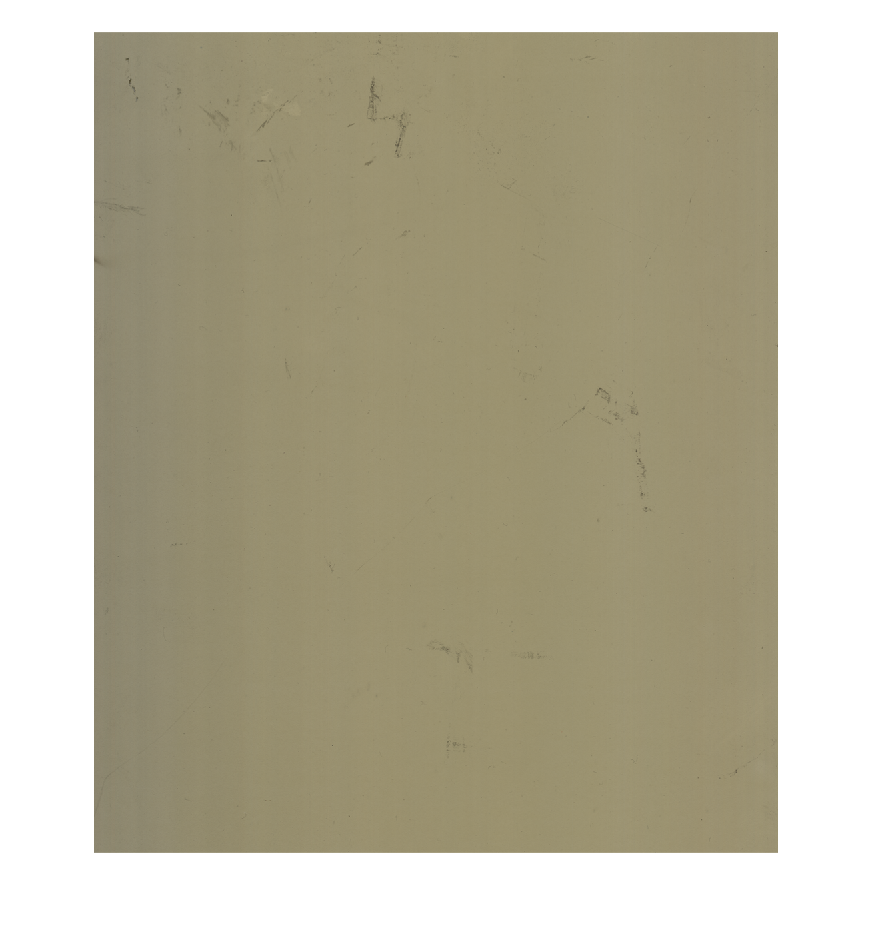



% Dibujar 
imFinalR2 = uint16(zeros(recorte(4)+1,recorte(3)+1,3));
imFinalR2(:,:,1) = uint16(RRfinal2);
imFinalR2(:,:,2) = uint16(GRfinal2);
imFinalR2(:,:,3) = uint16(BRfinal2);
figure
imshow(imFinalR2)

#### Variación horizontal

juntasmeanHR2 = zeros(size(mean(double(I1R(:,:,1)) / maxBitNumber),1),size(mean(double(I1R(:,:,1)) / maxBitNumber),2),3,2);
%Promedio: 1x1183

%Rojo
juntasmeanHR2(:,:,1,1) = mean(double(I5R(:,:,1)) / maxBitNumber);
juntasmeanHR2(:,:,1,2) = mean(double(I6R(:,:,1)) / maxBitNumber);


%Verde
juntasmeanHR2(:,:,2,1) = mean(double(I5R(:,:,2)) / maxBitNumber);
juntasmeanHR2(:,:,2,2) = mean(double(I6R(:,:,2)) / maxBitNumber);


%Azul
juntasmeanHR2(:,:,3,1) = mean(double(I5R(:,:,3)) / maxBitNumber);
juntasmeanHR2(:,:,3,2) = mean(double(I6R(:,:,3)) / maxBitNumber);

desvRmeanHR2 = std(juntasmeanHR2(:,:,1,:),0,4)

desvRmeanHR2 =     0.0004    0.0003    0.0005    0.0008    0.0007    0.0006    0.0005    0.0005    0.0004    0.0006    0.0007    0.0016    0.0010    0.0006    0.0009    0.0008    0.0004    0.0011    0.0005    0.0007    0.0012    0.0013    0.0011    0.0007    0.0010    0.0002    0.0008    0.0008    0.0005    0.0007    0.0006    0.0005    0.0009    0.0007    0.0013    0.0005    0.0003    0.0011    0.0005    0.0003    0.0006    0.0006    0.0002    0.0012    0.0007    0.0004    0.0009    0.0005    0.0013    0.0005


desvGmeanHR2 = std(juntasmeanHR2(:,:,2,:),0,4)

desvGmeanHR2 =     0.0003    0.0002    0.0003    0.0006    0.0004    0.0004    0.0000    0.0007    0.0005    0.0005    0.0005    0.0003    0.0005    0.0005    0.0003    0.0008    0.0008    0.0007    0.0003    0.0002    0.0006    0.0003    0.0006    0.0004    0.0005    0.0002    0.0003    0.0002    0.0003    0.0004    0.0004    0.0001    0.0003    0.0009    0.0007    0.0005    0.0003    0.0000    0.0002    0.0003    0.0004    0.0003    0.0003    0.0003    0.0002    0.0009    0.0009    0.0001    0.0001    0.0002


desvBmeanHR2 = std(juntasmeanHR2(:,:,3,:),0,4)

desvBmeanHR2 =     0.0004    0.0001    0.0002    0.0000    0.0001    0.0001    0.0000    0.0003    0.0001    0.0004    0.0003    0.0002    0.0001    0.0008    0.0001    0.0002    0.0003    0.0003    0.0002    0.0001    0.0006    0.0002    0.0002    0.0002    0.0001    0.0002    0.0003    0.0002    0.0004    0.0002    0.0004    0.0003    0.0000    0.0001    0.0002    0.0002    0.0001    0.0004    0.0001    0.0004    0.0003    0.0005    0.0001    0.0000    0.0002    0.0000    0.0003    0.0000    0.0003    0.0001



%Variación horizontal de la media

%desviación estándar de los elementos de cada fila 1500x1
%Rojo
dsv_MediaRmeanHfR2=std(mean(juntasmeanHR2(:,:,1,:),4),0,2)

dsv_MediaRmeanHfR2 = 0.0165

%Verde
dsv_MediaGmeanHfR2=std(mean(juntasmeanHR2(:,:,2,:),4),0,2)

dsv_MediaGmeanHfR2 = 0.0132

%Azul
dsv_MediaBmeanHfR2=std(mean(juntasmeanHR2(:,:,3,:),4),0,2)

dsv_MediaBmeanHfR2 = 0.0051

#### Variación vertical

juntasmeanVR2 = zeros(size(mean(double(I1R(:,:,1)) / maxBitNumber,2),1),size(mean(double(I1R(:,:,1)) / maxBitNumber,2),2),3,6);

%Promedio: 1500x1
%Rojo
juntasmeanVR2(:,:,1,1) = mean(double(I5R(:,:,1)) / maxBitNumber,2);
juntasmeanVR2(:,:,1,2) = mean(double(I6R(:,:,1)) / maxBitNumber,2);

%Verde
juntasmeanVR2(:,:,2,1) = mean(double(I5R(:,:,2)) / maxBitNumber,2);
juntasmeanVR2(:,:,2,2) = mean(double(I6R(:,:,2)) / maxBitNumber,2);

%Azul
juntasmeanVR2(:,:,3,1) = mean(double(I5R(:,:,3)) / maxBitNumber,2);
juntasmeanVR2(:,:,3,2) = mean(double(I6R(:,:,3)) / maxBitNumber,2);



desvRmeanVR2 = std(juntasmeanVR2(:,:,1,:),0,4)

desvRmeanVR2 =     0.3105
    0.3105
    0.3103
    0.3102
    0.3101
    0.3102
    0.3102
    0.3101
    0.3101
    0.3102


desvGmeanVR2 = std(juntasmeanVR2(:,:,2,:),0,4)

desvGmeanVR2 =     0.2945
    0.2945
    0.2942
    0.2941
    0.2940
    0.2941
    0.2941
    0.2940
    0.2939
    0.2941


desvBmeanVR2 = std(juntasmeanVR2(:,:,3,:),0,4)

desvBmeanVR2 =     0.2319
    0.2318
    0.2316
    0.2314
    0.2314
    0.2313
    0.2312
    0.2312
    0.2312
    0.2312



%Variación vertical de la media
%desviación estándar de los elementos de cada columna 1x1183
dsv_MediameanVRf2=std(mean(juntasmeanVR2(:,:,1,:),4),0,1)

dsv_MediameanVRf2 = 6.5568e-04

dsv_MediaGmeanVRf2=std(mean(juntasmeanVR2(:,:,2,:),4),0,1)

dsv_MediaGmeanVRf2 = 7.4521e-04

dsv_MediaBmeanVRf2=std(mean(juntasmeanVR2(:,:,3,:),4),0,1)

dsv_MediaBmeanVRf2 = 0.0011

**Comparar las dos radiocrómicas**

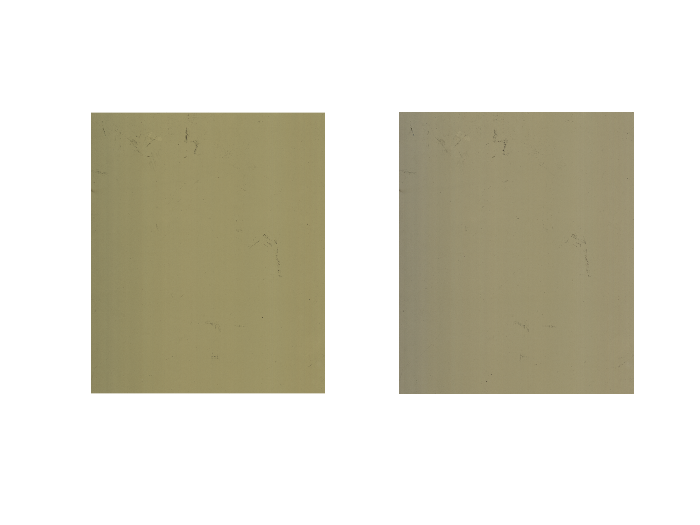

figure
subplot(1,2,1)
imshow(imFinalR)
subplot(1,2,2)
imshow(imFinalR2)


%Construir matrices que representen las desviaciones pixel a pixel
DesviacionPromediosR=abs((RRfinal2-RRfinal)*100./RRfinal)

DesviacionPromediosR =     0.2284    0.1484    0.3302    0.1674    0.1793    0.0947    0.0164    0.3693    0.0983    0.0840    0.0509    0.1601    0.0942    0.2200    0.2930    0.0189    0.2320    0.0244    0.1167    0.0188    0.0431    0.0027    0.0326    0.0758    0.2017    0.0656    0.0082    0.0972    0.0595    0.0135    0.0241    0.0839    0.0218    0.0134    0.1907    0.1399    0.0569    0.3235    0.2695    0.2212    0.0619    0.0648    0.1058         0    0.1137    0.0727    0.3594    0.0397    0.1490    0.0663
    0.3642    0.1021    0.1578    0.1495    0.1276    0.0462    0.0715    0.0797    0.1516    0.2079    0.1414    0.0109    0.0348    0.1641    0.0163    0.0514    0.0514    0.0813    0.0813    0.0323    0.1060    0.0781    0.0758    0.2658    0.3107    0.0464    0.0429    0.1444    0.0136    0.1442    0.0214    0.0786    0.0217    0.0081    0.2160    0.0973    0.0327    0.0243    0.2755    0.2622    0.0955    0.1069    0.0491    0.2380    0.0647    0.0830    0.2709    0.

DesviacionPromediosG=abs((GRfinal2-GRfinal)*100./GRfinal)

DesviacionPromediosG =     0.2487    0.0658    0.0086    0.0339    0.0140    0.0817    0.2954    0.0750    0.1084    0.0056    0.0840    0.0028    0.0645    0.1711    0.2422    0.2019    0.2544    0.1595    0.1541    0.1181    0.0474    0.0528    0.1671    0.0452    0.0056    0.0398    0.1135    0.0028    0.2108    0.0113    0.0480    0.0394    0.0282    0.0083    0.0280    0.0223    0.2136    0.0250    0.0869    0.3204    0.0168    0.1401    0.1439    0.1815    0.0140    0.0196    0.0726    0.0970    0.0389    0.1521
    0.2550    0.1008    0.0713    0.0740    0.0824    0.1383    0.2953    0.1749    0.0564    0.0677    0.0613    0.0424    0.0028    0.0169    0.0479    0.0197    0.1462    0.2072    0.0476    0.0816    0.0368    0.1347    0.1719    0.0481    0.1415    0.0171    0.0056    0.0056    0.1409    0.0835    0.1014    0.1828    0.0084    0.1176    0.0365    0.0392    0.2307    0.0056    0.2002    0.1877    0.2147    0.0944    0.1051    0.1508    0.0866    0.2776    0.1573    0.

DesviacionPromediosB=abs((BRfinal2-BRfinal)*100./BRfinal)

DesviacionPromediosB =    16.5136   16.8431   16.4749   16.5474   16.6990   16.6373   16.6990   16.2789   16.5380   16.6347   16.5477   16.3693   16.1388   16.5787   16.1370   15.7592   15.7733   16.0513   16.1375   15.7640   15.7703   15.7688   15.5627   15.6503   15.9261   15.6435   15.8003   15.7088   15.6972   15.4917   15.4579   15.4259   15.7025   15.5140   15.5396   15.5972   15.5655   15.2372   15.2896   15.3559   15.2295   14.9691   15.2324   15.5170   15.3487   15.1807   15.2099   14.9284   14.9513   15.3564
   16.6121   16.8220   16.7021   16.5500   16.6957   16.6072   16.6647   16.5142   16.4175   16.5551   16.4390   16.3886   16.3451   16.4455   16.2288   15.8766   16.0784   15.9259   16.0245   15.8642   15.7699   15.8146   15.9828   15.4330   15.6150   16.0139   15.7018   15.4562   15.6085   15.6019   15.6012   15.3907   15.7676   15.3646   15.4067   15.7347   15.5101   15.4258   15.2957   15.5619   15.4112   14.9813   15.2652   15.6596   15.2523   15.1668   15.2541   15.

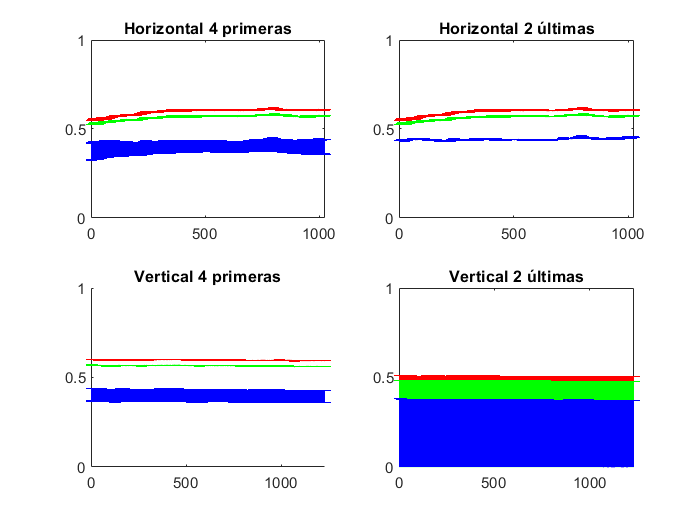


figure
%Horizontal
subplot(2,2,1)
hold off
plot(mean(juntasmeanHR(:,:,1,:),4),'r'); hold on
plot(mean(juntasmeanHR(:,:,2,:),4),'g');
plot(mean(juntasmeanHR(:,:,3,:),4),'b')
title('Horizontal 4 primeras')
errorbar(mean(juntasmeanHR(:,:,1,:),4),desvRmeanHR,'r')
errorbar(mean(juntasmeanHR(:,:,2,:),4),desvGmeanHR,'g')
errorbar(mean(juntasmeanHR(:,:,3,:),4),desvBmeanHR,'b')
ylim([0 1])
xlim([0 recorte(3)+1])


subplot(2,2,2)
hold off
plot(mean(juntasmeanHR2(:,:,1,:),4),'r'); hold on
plot(mean(juntasmeanHR2(:,:,2,:),4),'g');
plot(mean(juntasmeanHR2(:,:,3,:),4),'b')
title('Horizontal 2 últimas')
errorbar(mean(juntasmeanHR2(:,:,1,:),4),desvRmeanHR2,'r')
errorbar(mean(juntasmeanHR2(:,:,2,:),4),desvGmeanHR2,'g')
errorbar(mean(juntasmeanHR2(:,:,3,:),4),desvBmeanHR2,'b')
ylim([0 1])
xlim([0 recorte(3)+1])

%Vertical
subplot(2,2,3)
hold on 
plot(mean(juntasmeanVR(:,:,1,:),4),'r'); hold on
plot(mean(juntasmeanVR(:,:,2,:),4),'g');
plot(mean(juntasmeanVR(:,:,3,:),4),'b')
title('Vertical 4 primeras')
errorbar(mean(juntasmeanVR(:,:,1,:),4),desvRmeanVR,'r')
errorbar(mean(juntasmeanVR(:,:,2,:),4),desvGmeanVR,'g')
errorbar(mean(juntasmeanVR(:,:,3,:),4),desvBmeanVR,'b')
ylim([0 1])
xlim([0 recorte(4)+1])

subplot(2,2,4)
hold off
plot(mean(juntasmeanVR2(:,:,1,:),4),'r'); hold on
plot(mean(juntasmeanVR2(:,:,2,:),4),'g');
plot(mean(juntasmeanVR2(:,:,3,:),4),'b')
title('Vertical 2 últimas')
errorbar(mean(juntasmeanVR2(:,:,1,:),4),desvRmeanVR2,'r')
errorbar(mean(juntasmeanVR2(:,:,2,:),4),desvGmeanVR2,'g')
errorbar(mean(juntasmeanVR2(:,:,3,:),4),desvBmeanVR2,'b')
ylim([0 1])
xlim([0 recorte(4)+1])